# WHEEL MOBILE ROBOTS - KINEMATICS

## Lab by Mikołaj Suchoń

### Assumptions:

We asume a two wheeled mobile robot along a path consisting of 5 different segments:

Startup, straight line movement, arc movement, straignt line movement, deceleration and stop.

Acceleration time: 2s

Max speed: 1m/s

Straight line movement: 1s

Arc movement: 0.5s R=4m

Straight line movement: 0.5s

Decceleration time: 2s

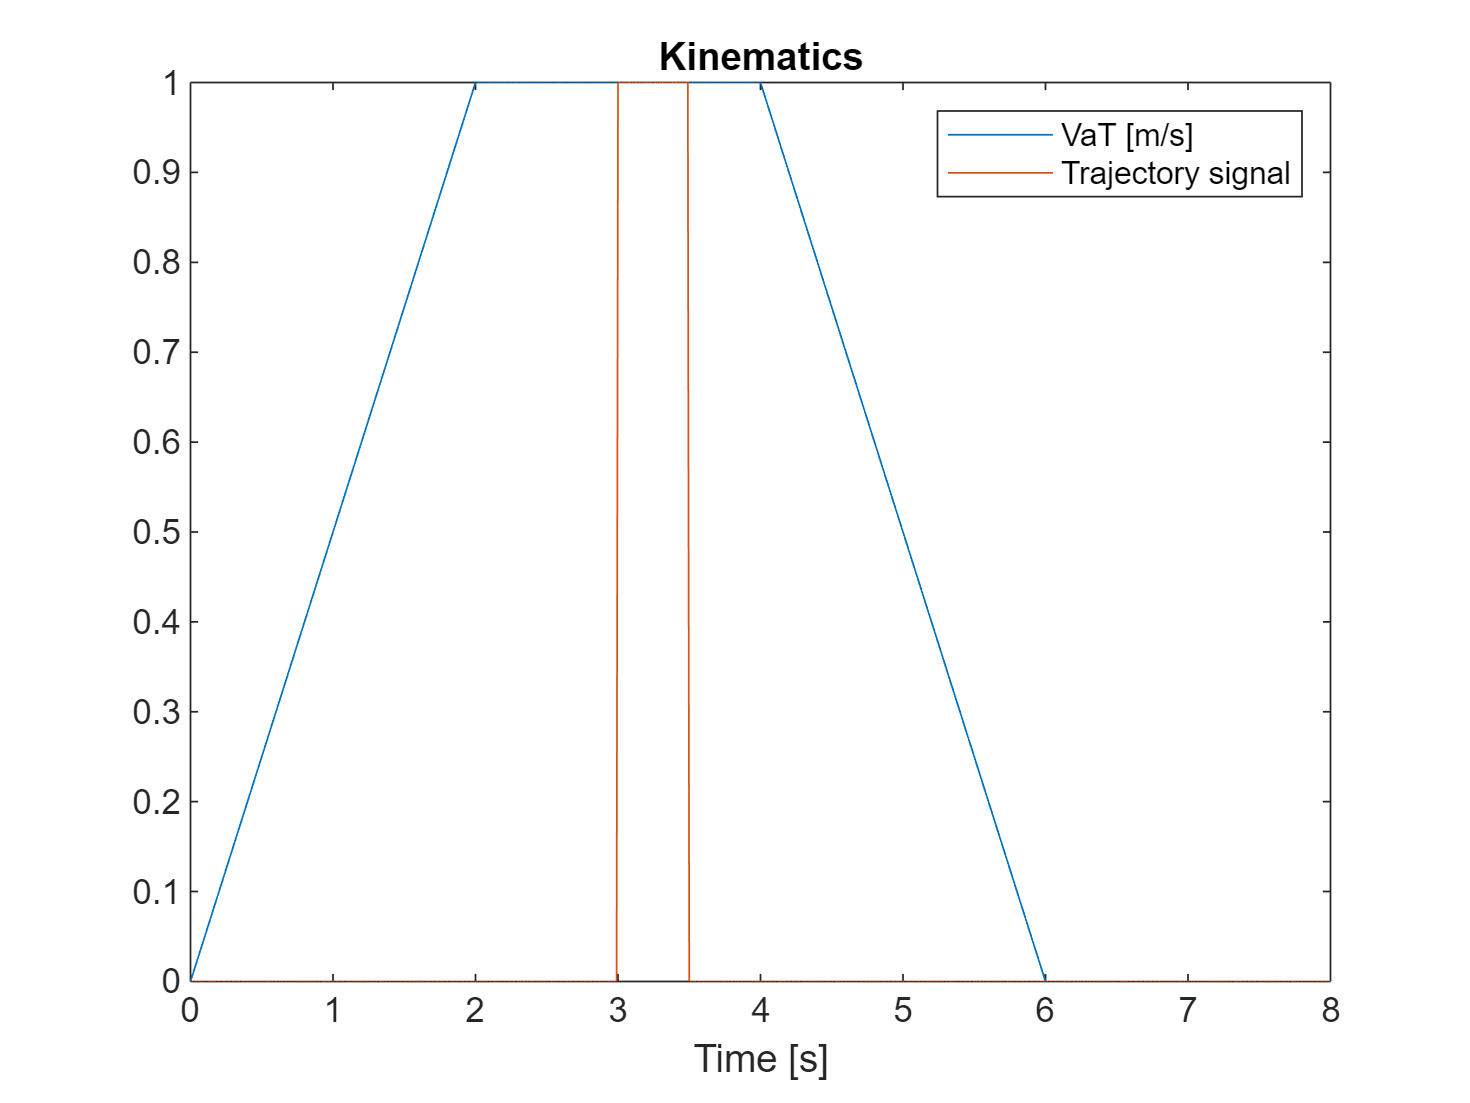

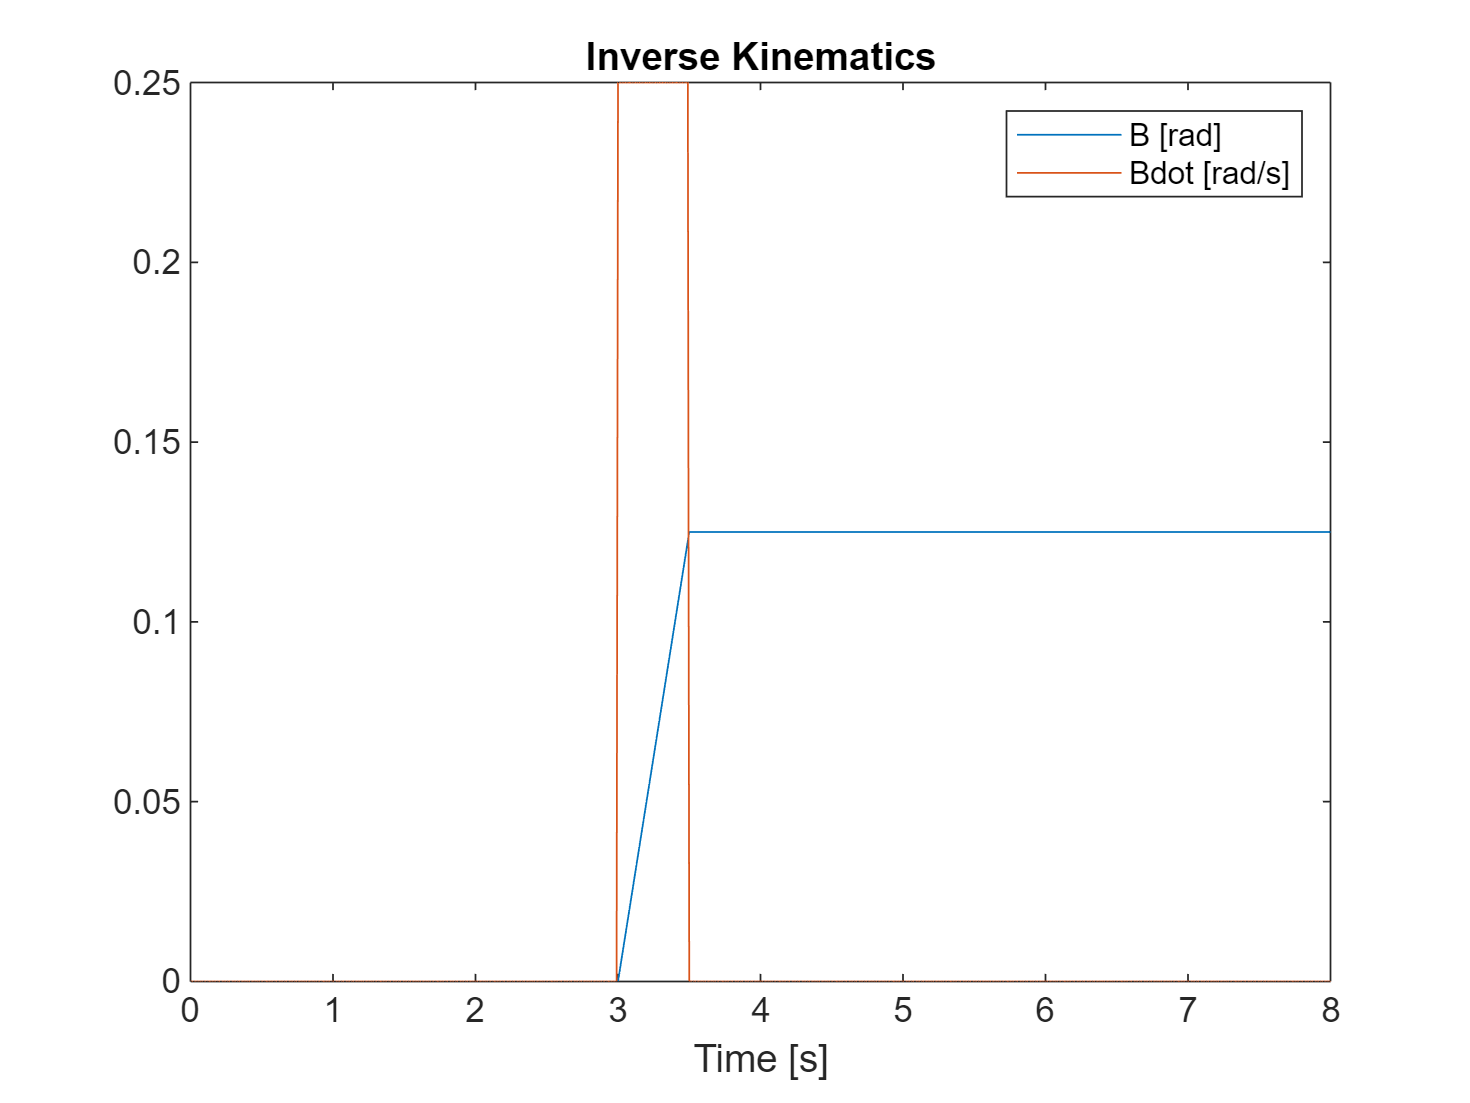

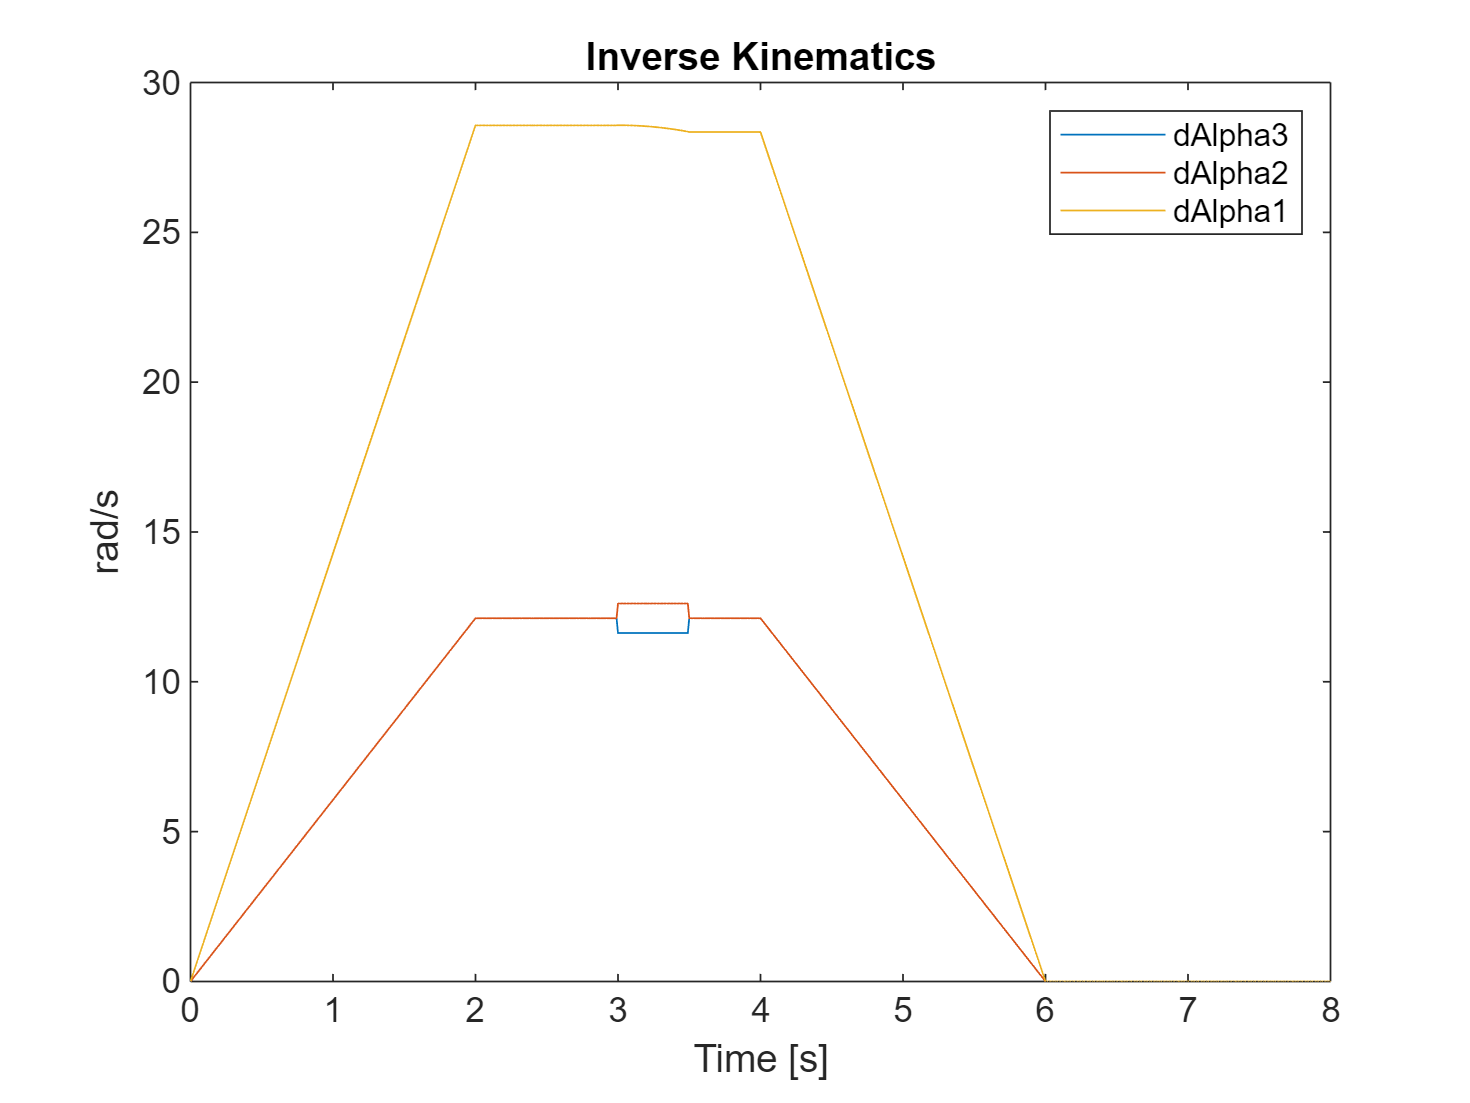

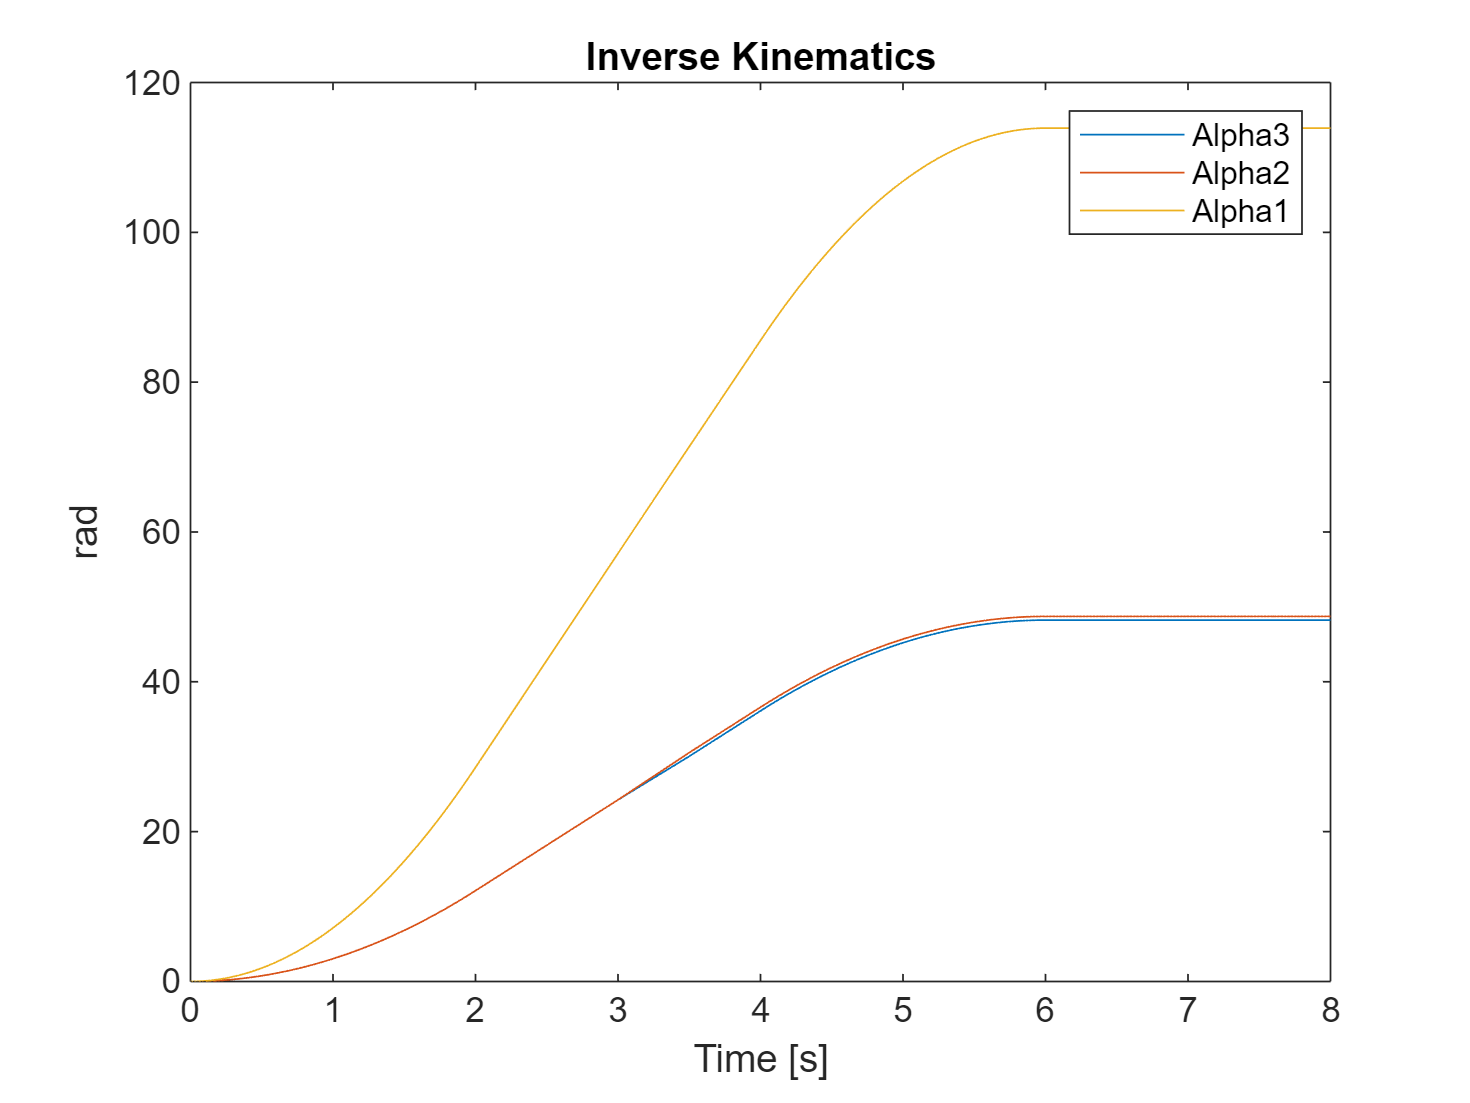

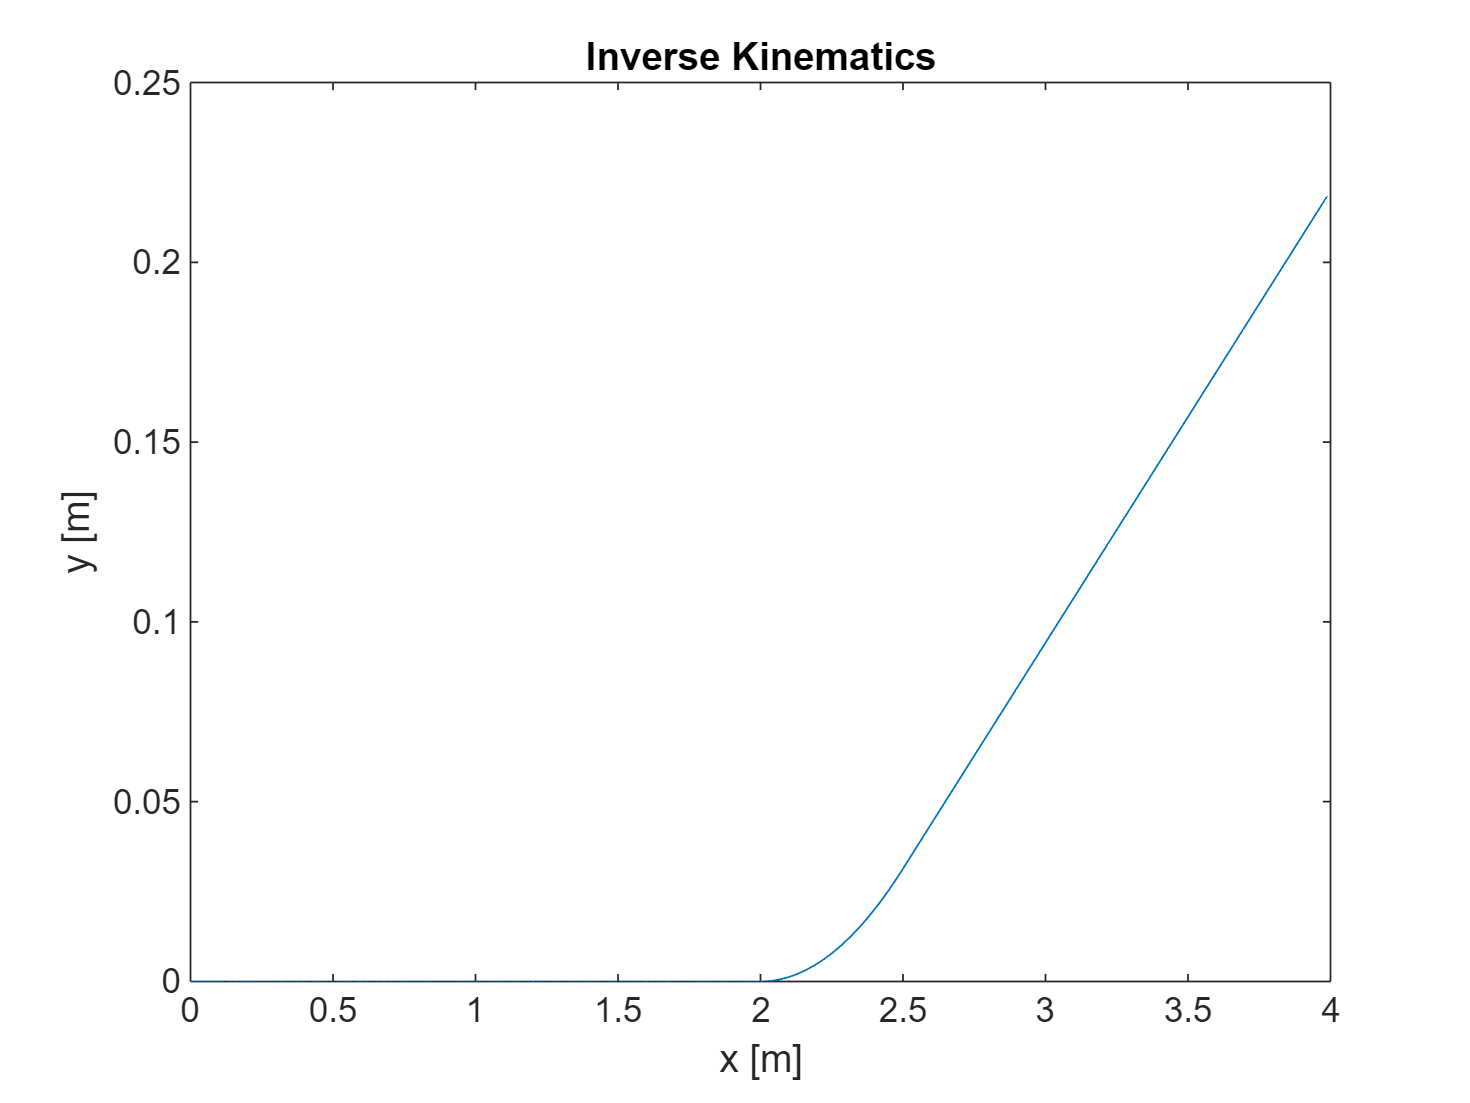

clear 
load out.mat
dataobj=out.simout;
labPlot(dataobj)

-------------------------------


### Assumptions 2:

We asume a two wheeled mobile robot along a path consisting of 5 different segments:

Startup, straight line movement, arc movement, straignt line movement, deceleration and stop.

Acceleration time: 2s

Max speed: 1m/s

Straight line movement: 1s

Arc movement: 2s R=4m

Straight line movement: 1s

Decceleration time: 2s

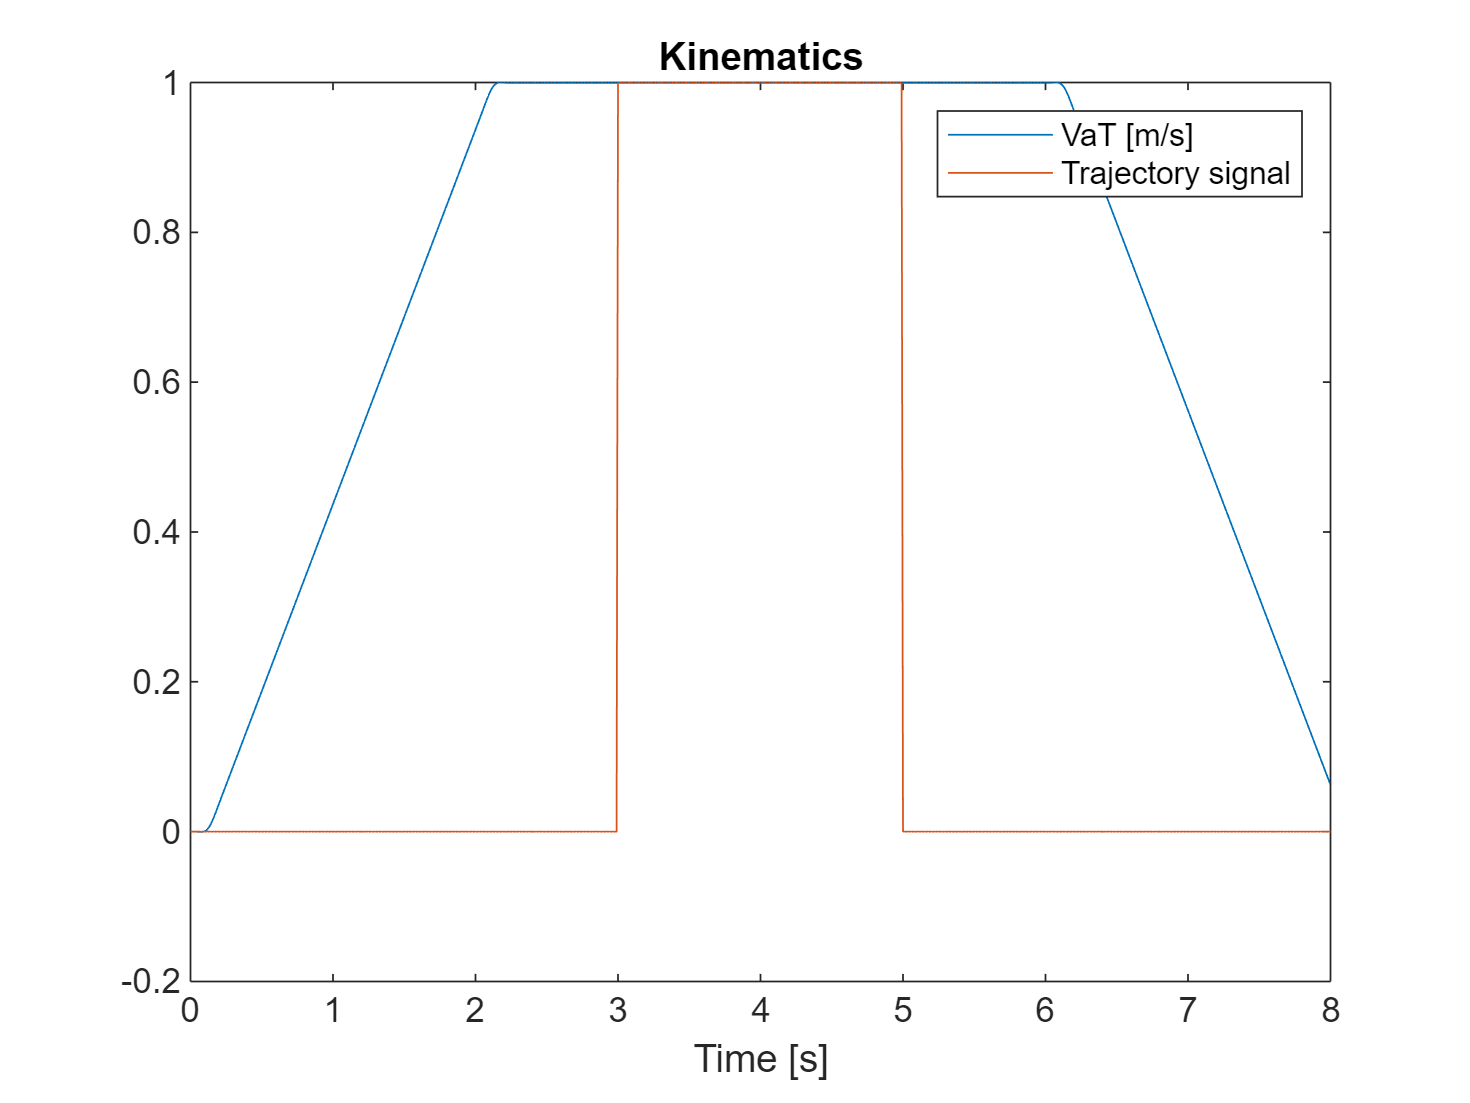

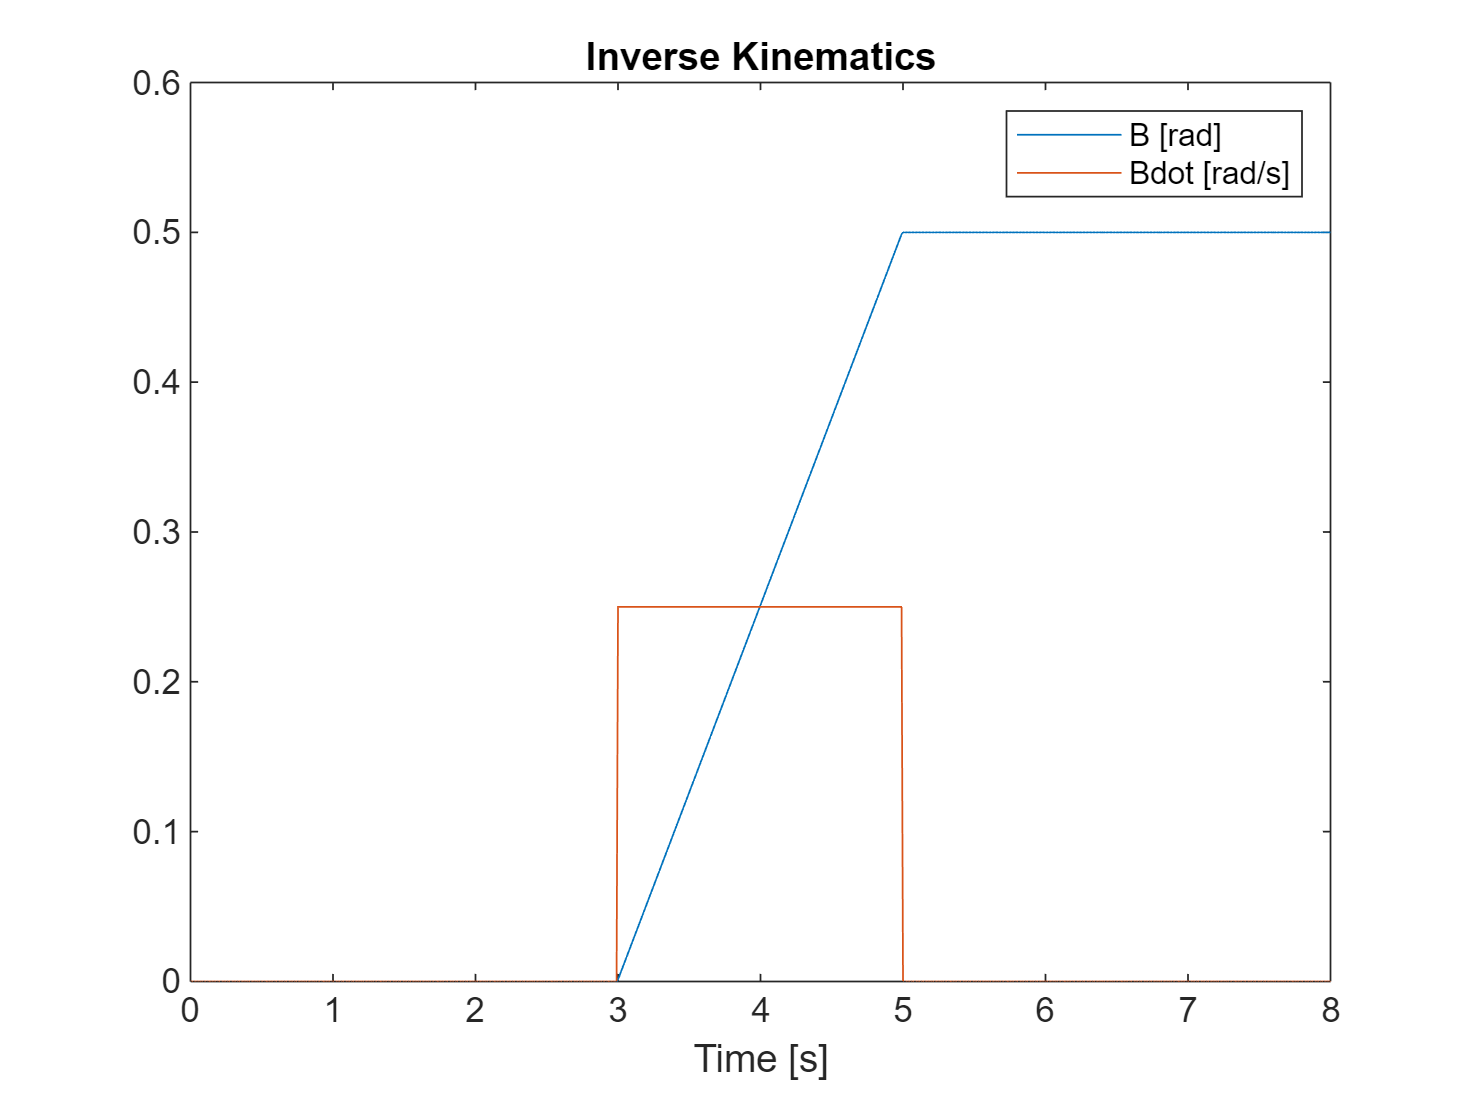

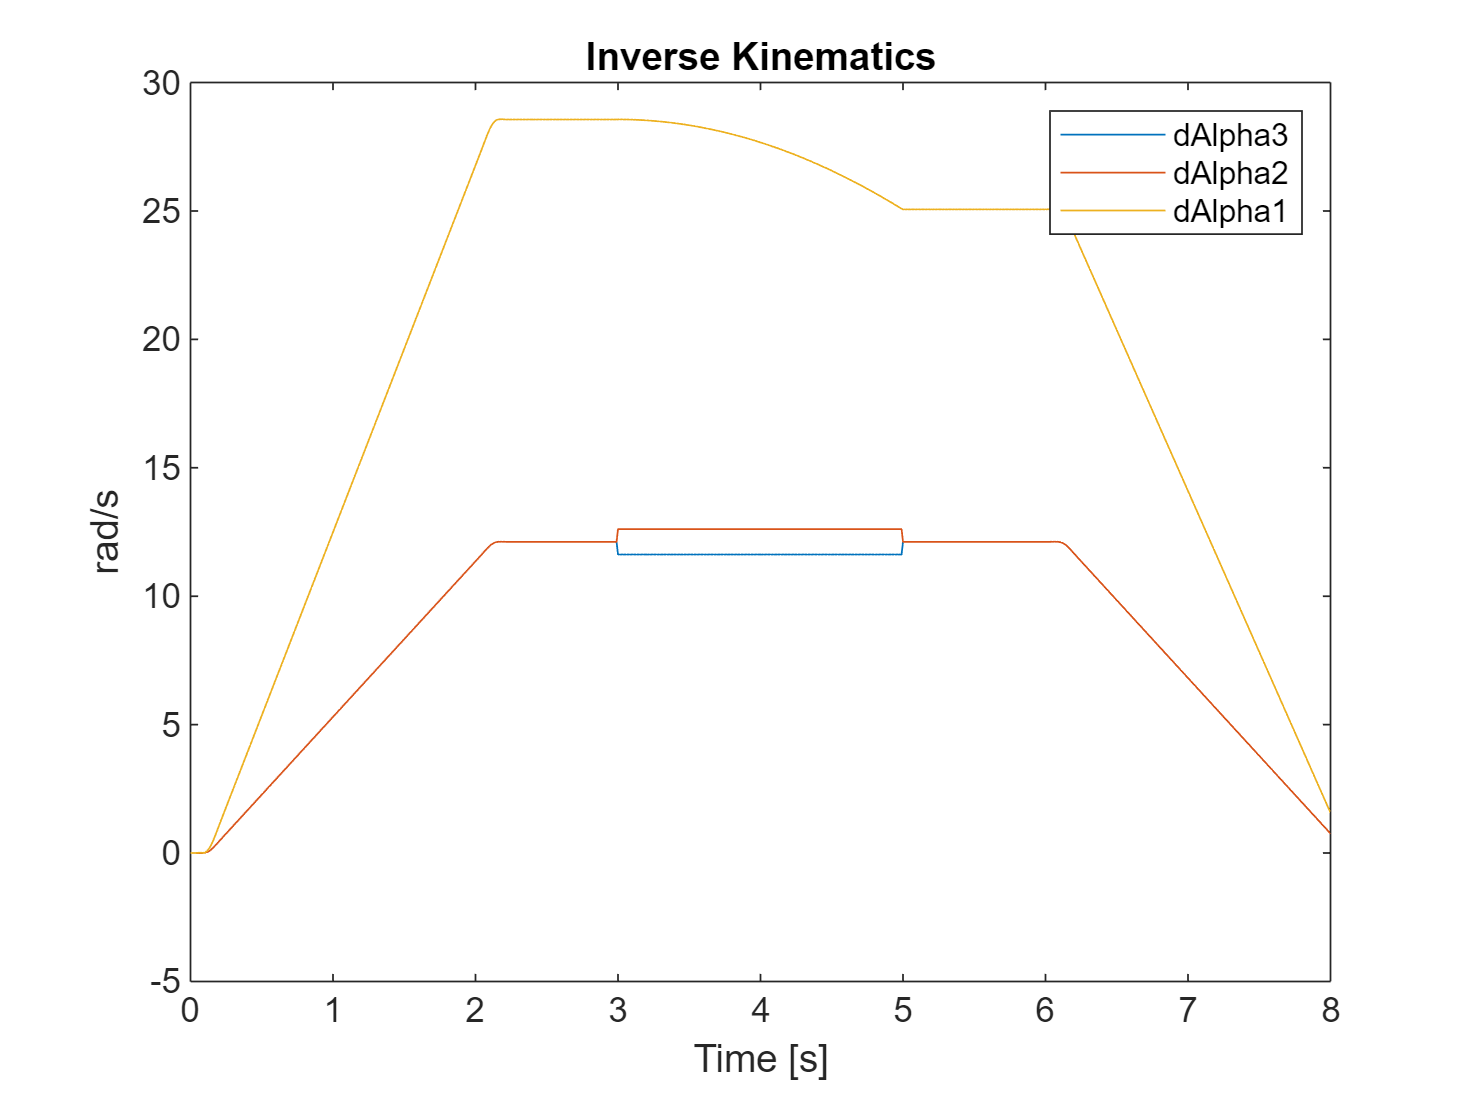

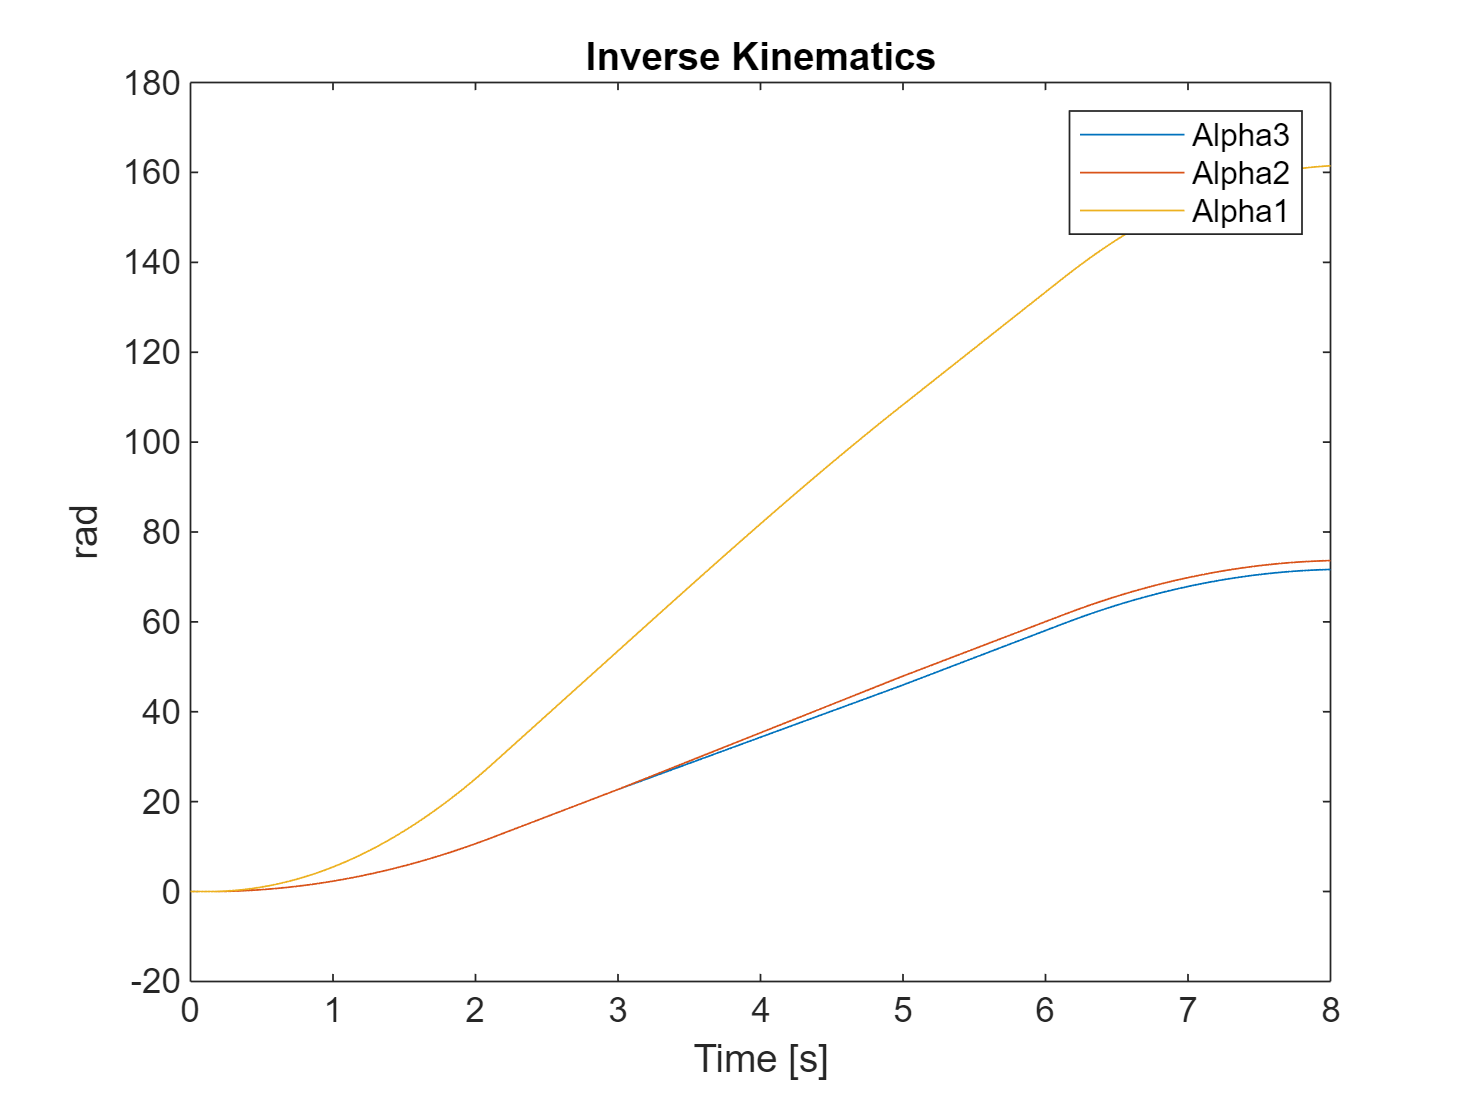

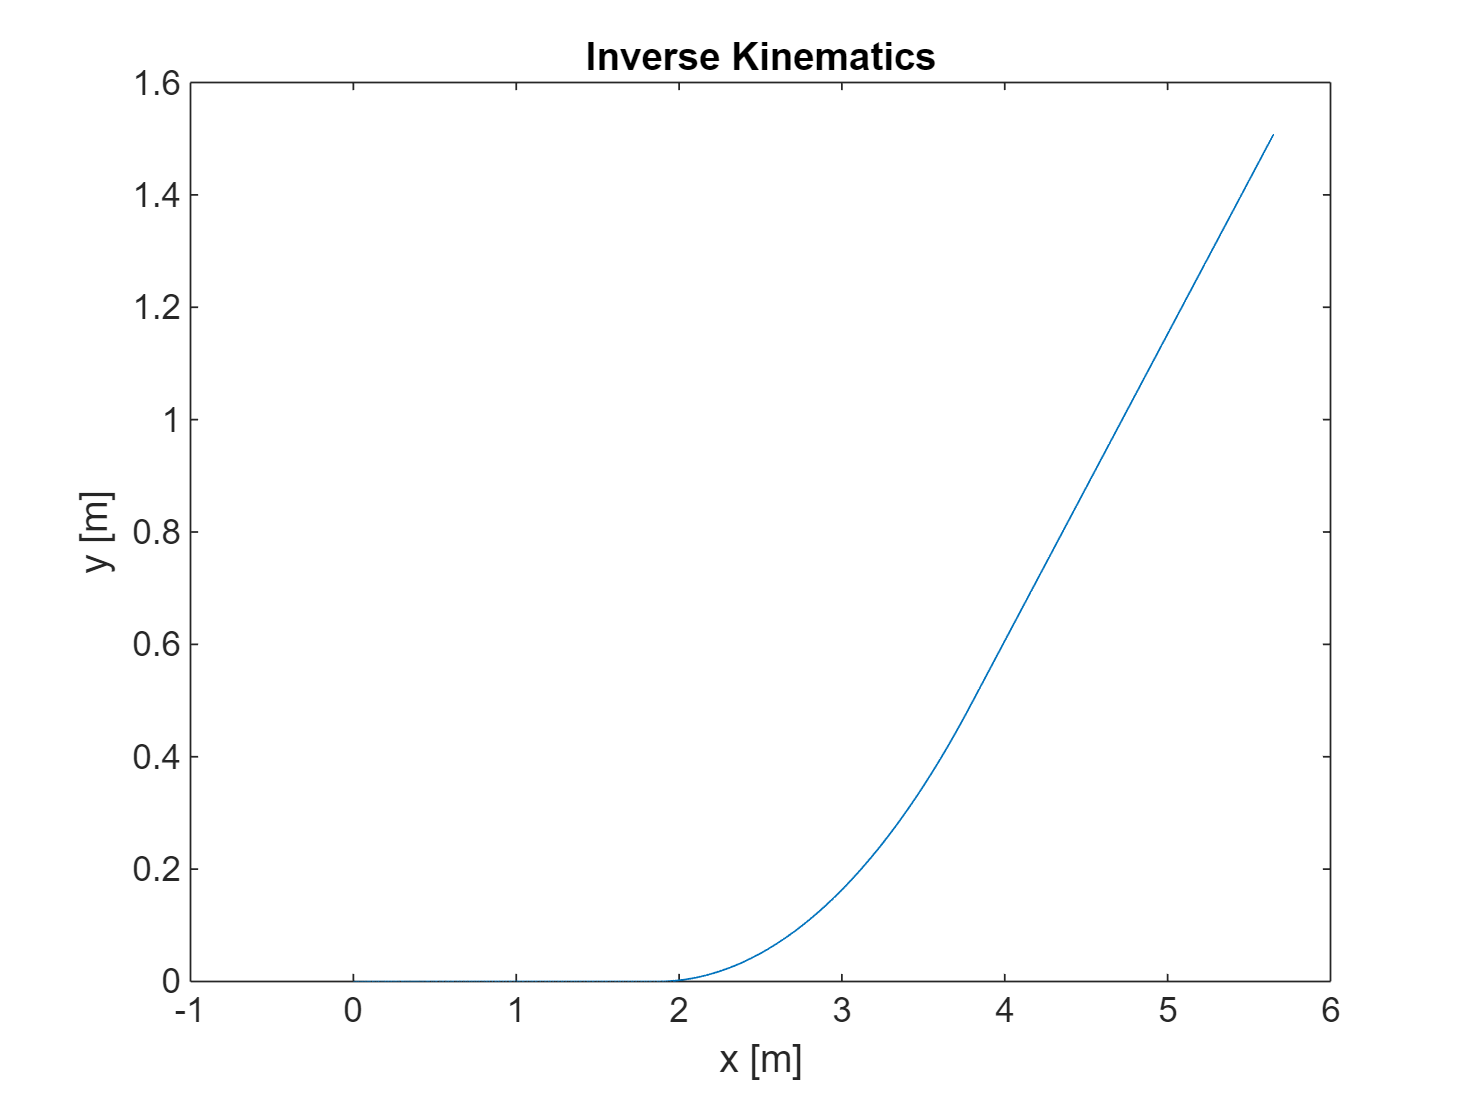

dataobj2=out.simout1;
labPlot(dataobj2)

function labPlot(dataobj)
t=dataobj.Time;
VaT=dataobj.Data(:,2);
sig=dataobj.Data(:,1);
figure
plot(t,VaT,t,sig)
title('Kinematics')
xlabel('Time [s]')
legend('VaT [m/s]','Trajectory signal')

B=dataobj.Data(:,4);
Bdot=dataobj.Data(:,3);
figure
plot(t,B,t,Bdot)
title('Inverse Kinematics')
xlabel('Time [s]')
legend('B [rad]','Bdot [rad/s]')

a1=dataobj.Data(:,7);
a2=dataobj.Data(:,8);
a3=dataobj.Data(:,9);
figure
plot(t,a1,t,a2,t,a3)
title('Inverse Kinematics')
xlabel('Time [s]')
ylabel('rad/s')
legend('dAlpha3','dAlpha2','dAlpha1')

da1=dataobj.Data(:,10);
da2=dataobj.Data(:,11);
da3=dataobj.Data(:,12);
figure
plot(t,da1,t,da2,t,da3)
title('Inverse Kinematics')
xlabel('Time [s]')
ylabel('rad')
legend('Alpha3','Alpha2','Alpha1')

x=dataobj.Data(:,5);
y=dataobj.Data(:,6);
figure
plot(x,y)
title('Inverse Kinematics')
xlabel('x [m]')
ylabel('y [m]')
end


